## **2ª prova de Robótica do período 2023/1**

clear; clc;
import RoboticaBiblioteca.*

maoDireita()

--- Regra da mão Direita ---
     eixo x --- indicador
     eixo y --- meio
     eixo z --- dedão
----------------------------
ver palma da mão -> positivo
para z: < positivo | > negativo
para x: palma da mão pra cima - positivo | palma da mão pra baixo - negativo
para y: pistola pra baixo - positivo | pistola pra cima - negativo


**Questão 1) (8,0 pts)** A imagem abaixo foi retirada do manual do fabricante, onde apresenta o comprimentos dos links, bem como o envelope de trabalho de um manipulador que possui 6 graus de liberdade sendo caracterizado como um manipulador antropomórfico com um pulso rotacional

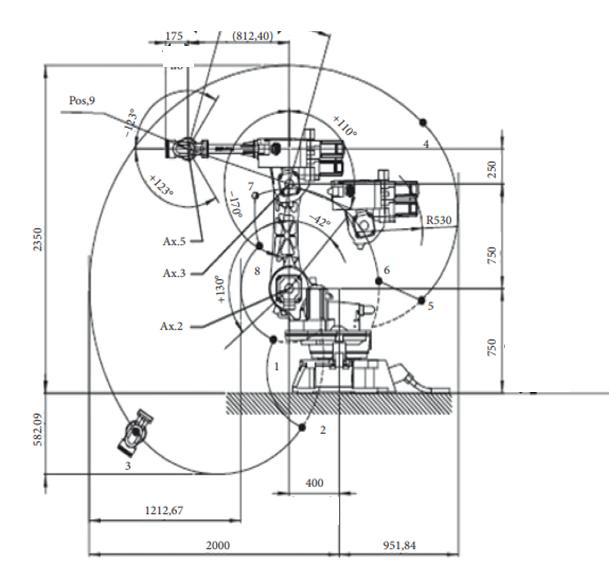

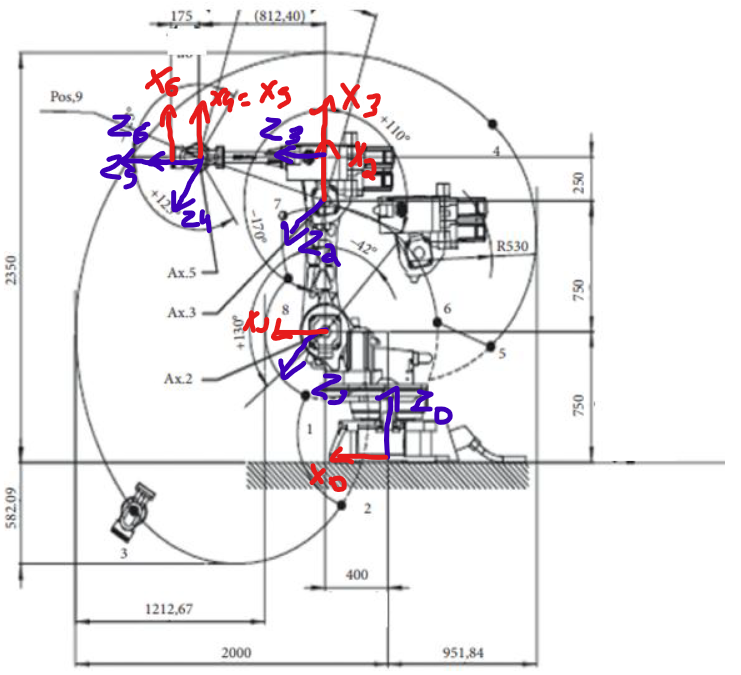

a) Faça a alocação dos frames, segundo a teoria de D.H. de cada junta do referido manipulador

|  link  |   a   | alpha |    d    |      theta       |

| 0 - 1 | 400 |   -90   |  750  |    theta1*     |  R

| 1 - 2 | 750 |     0    |    0     | theta2* - 90|  R

| 2 - 3 | 250 |   -90   |    0    |    theta3*     |  P

| 3 - 4 |   0   |  +90   | 812,4|    theta4*     |  R }

| 4 - 5 |   0   |   -90   |    0    |    theta5*     |  R }  Punho esférico

| 5 - 6 |   0   |     0    |  175  |    theta6*     |  R }

b) Desenvolva a Tabela de Denavit-Hartemberg e determine as matrizes parciais e a matriz total para:

                                        [θ1 = 25, θ2 = 40, θ3 = 60, θ4 = 90, θ5 = 0, θ6 = 30]

theta1 = 25;
theta2 = 40;
theta3 = 60;
theta4 = 90;
theta5 = 0;
theta6 = 30;

DH = [400 -90 750 theta1;
      750 0 0 (theta2 - 90);
      250 -90 0 theta3;
      0 +90 812.4 theta4;
      0 -90 0 theta5;
      0 0 175 theta6];
[H06, Alc] = MatProgDenavit(DH)

A01 = 
    0.9063         0   -0.4226  362.5231
    0.4226         0    0.9063  169.0473
         0   -1.0000         0  750.0000
         0         0         0    1.0000

A12 = 
    0.6428    0.7660         0  482.0907
   -0.7660    0.6428         0 -574.5333
         0         0    1.0000         0
         0         0         0    1.0000

A23 = 
    0.5000         0   -0.8660  125.0000
    0.8660         0    0.5000  216.5064
         0   -1.0000         0         0
         0         0         0    1.0000

A34 = 
         0         0    1.0000         0
    1.0000         0         0         0
         0    1.0000         0  812.4000
         0         0         0    1.0000

A45 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A56 = 
    0.8660   -0.5000         0         0
    0.5000    0.8660         0         0
         0         0    1.0000  175.0000
         0         0         0    1.0000



H06 =    -0.0803   -0.9843   -0.1574  867.1847
   -0.9930    0.0927   -0.0734  404.3749
    0.0868    0.1504   -0.9848  308.7221
         0         0         0    1.0000


Alc = 1×6 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


c) Que ângulos e movimentos deveríamos fazer para criarmos a mesma configuração de posição e localização obtido em b, utilizando um manipulador Cilindrico-Euler?

d6 = 175;
d06 = H06(1:3, 4);
R06 = H06(1:3,1:3);
pc = PC(d06,d6,R06)

pc =   894.7260
  417.2176
  481.0635


[r, alpha, l] = movimentosTcil(pc(1),pc(2),pc(3));

r = 987.220866 | alpha = 25.000000 | L = 481.063469


T03 = Tcil(r, alpha, l)

T03 =     0.9063   -0.4226         0  894.7260
    0.4226    0.9063         0  417.2176
         0         0    1.0000  481.0635
         0         0         0    1.0000


R03 = T03(1:3,1:3);
R06 = H06(1:3,1:3);
R36 = (R03)^-1 * R06

R36 =    -0.4924   -0.8529   -0.1736
   -0.8660    0.5000   -0.0000
    0.0868    0.1504   -0.9848


[phi, theta, psi] = angsEuler(R36);

phi = -180.000000 | theta = 170.000000 | psi = 120.000000


**Questão 2) (4,0 pts)** A Figura abaixo apresenta o manipulador Universal com 6 DOF e um pulso não esférico. Os parâmetros Denavit-Hartenberg são dados na Tabela abaixo, junto com os valores numéricos para os parâmetros constantes e os valores atuais que as variáveis conjuntas assumem na configuração mostrada.

Desenhe de forma visível para correção, todos os parâmetros de Denavit-Hartenberg na imagem fornecida, conforme os valores apresentados na Tabela.

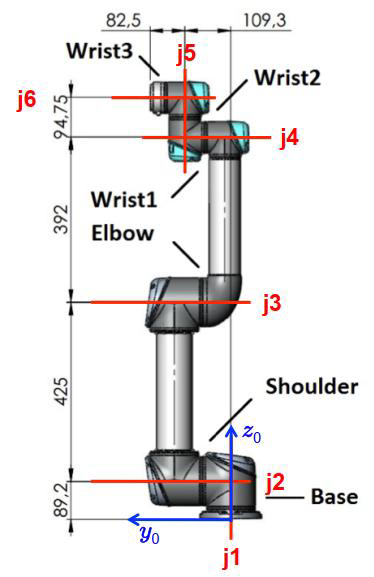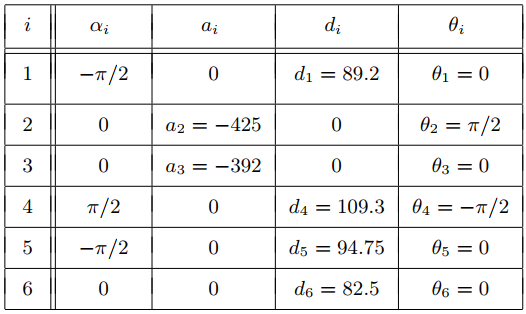

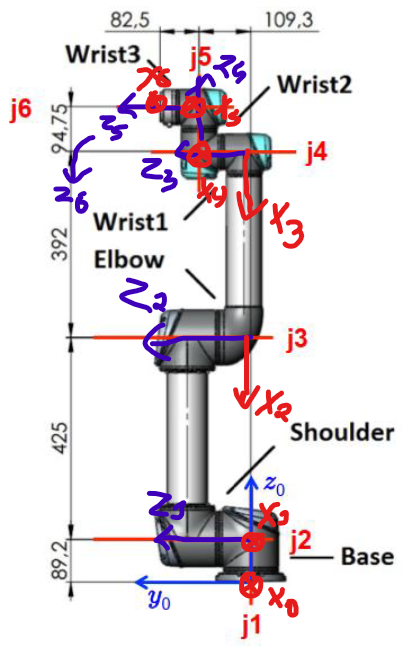

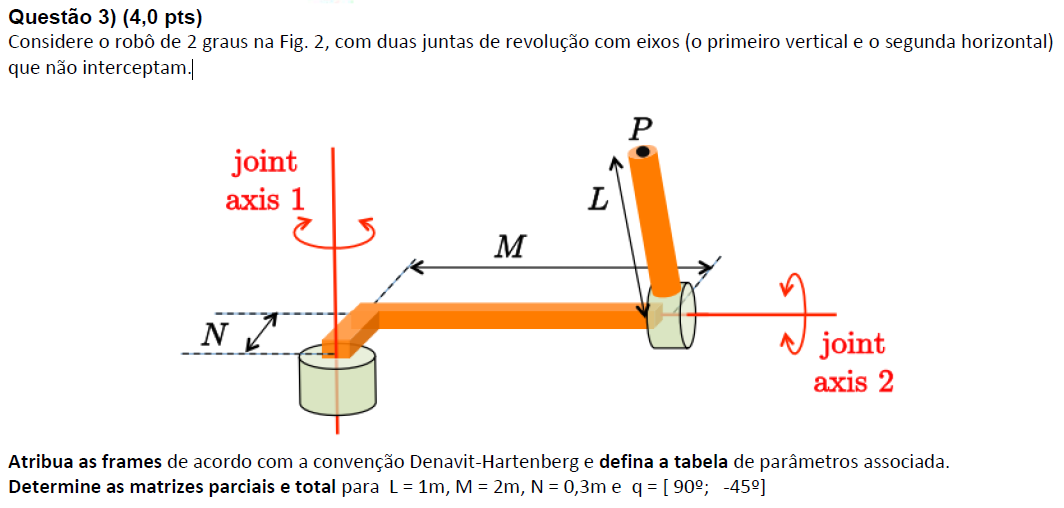

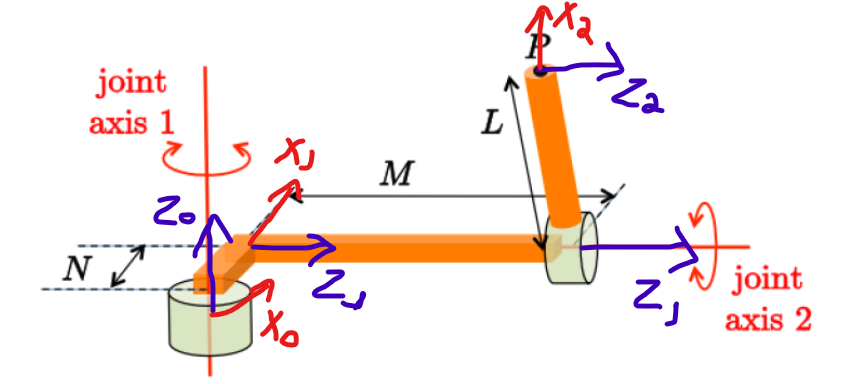

|  link  |   a   |  alpha |    d    |   theta   |

| 0 - 1 |   N   |    90   |     0   |  theta1* |   R

| 1 - 2 |   L    |     0    |    M   |  theta2* |  R

usarDenavit()

denavit(theta, d, a, alpha)


A01 = denavit(90, 0, 0.3, 90)

A01 =          0         0    1.0000         0
    1.0000         0         0    0.3000
         0    1.0000         0         0
         0         0         0    1.0000


A12 = denavit(-45, 2, 1, 0)

A12 =     0.7071    0.7071         0    0.7071
   -0.7071    0.7071         0   -0.7071
         0         0    1.0000    2.0000
         0         0         0    1.0000


A02 = A01*A12

A02 =          0         0    1.0000    2.0000
    0.7071    0.7071         0    1.0071
   -0.7071    0.7071         0   -0.7071
         0         0         0    1.0000


**Questão 4) (8,0 pts)** Considere o manipulador apresentado abaixo:

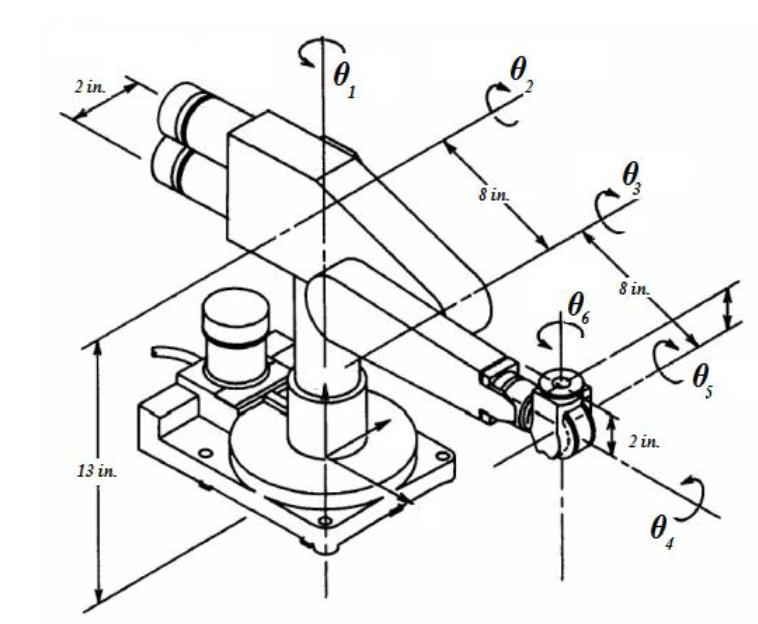

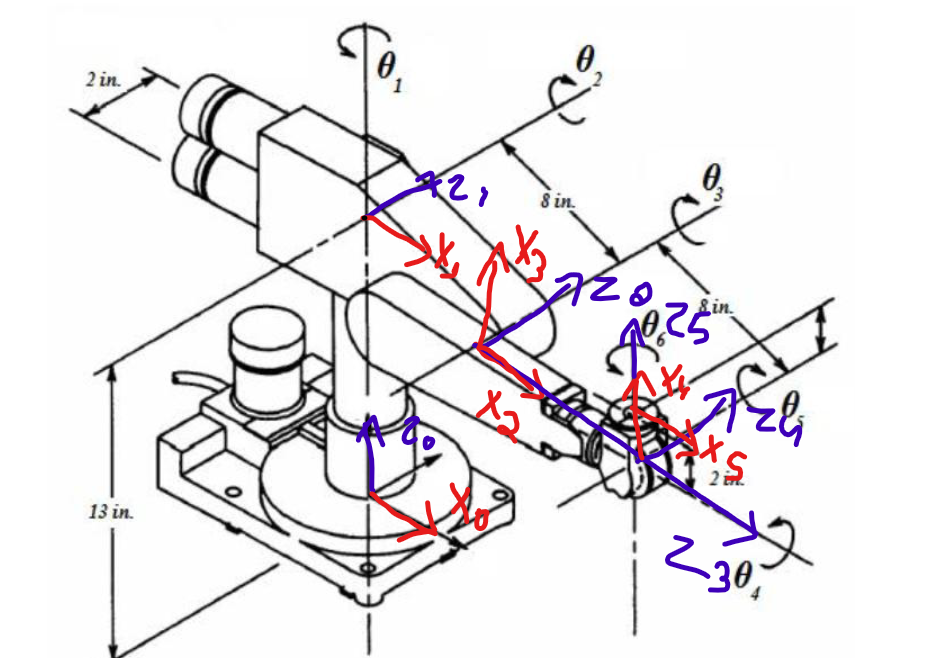

a) Faça a alocação das frames de cada junta do referido manipulador

b) Desenvolva a Tabela de Denavit-Hartemberg e determine as matrizes parciais e a matriz total para:

                                    [θ1 = 10, θ = 45, θ3 = 110, θ4 = 45, θ5 = 100, θ6 = 45]

Para efeitos de simplificação de cálculos, favor não acrescentar +/- 90º nos valores de θ

|  link  |   a   | alpha |    d    |      theta       |

| 0 - 1 |   0   |   -90   |   13    |    theta1*     |  R

| 1 - 2 |   8   |     0    |    2    |    theta2*      |  R

| 2 - 3 |   0   |   -90   |    0    | theta3* - 90 |  P

| 3 - 4 |   0   |  +90   |    8    |    theta4*      |  R }

| 4 - 5 |   0   |  +90   |    0    | theta5* + 90 |  R }  Punho esférico

| 5 - 6 |   0   |     0    |    2    |    theta6*      |  R }

theta1 = 10;
theta2 = 45;
theta3 = 110;
theta4 = 45;
theta5 = 100;
theta6 = 45;

DH = [0 -90 13 theta1;
      8 0 2 theta2;
      0 -90 0 theta3;
      0 +90 8 theta4;
      0 +90 0 theta5;
      0 0 2 theta6];
[H06, Alc] = MatProgDenavit(DH)

A01 = 
    0.9848         0   -0.1736         0
    0.1736         0    0.9848         0
         0   -1.0000         0   13.0000
         0         0         0    1.0000

A12 = 
    0.7071   -0.7071         0    5.6569
    0.7071    0.7071         0    5.6569
         0         0    1.0000    2.0000
         0         0         0    1.0000

A23 = 
   -0.3420         0   -0.9397         0
    0.9397         0   -0.3420         0
         0   -1.0000         0         0
         0         0         0    1.0000

A34 = 
    0.7071         0    0.7071         0
    0.7071         0   -0.7071         0
         0    1.0000         0    8.0000
         0         0         0    1.0000

A45 = 
   -0.1736         0    0.9848         0
    0.9848         0    0.1736         0
         0    1.0000         0         0
         0         0         0    1.0000

A56 = 
    0.7071   -0.7071         0         0
    0.7071    0.7071         0         0
         0         0    1.0000    2.0000
         0

H06 =    -0.7605   -0.3057   -0.5729    0.7483
    0.4618    0.3656   -0.8081    0.7486
    0.4565   -0.8791   -0.1369   14.3198
         0         0         0    1.0000


Alc = 1×6 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


c) Que ângulos e movimentos deveríamos fazer para criarmos a mesma configuração de posição e localização, utilizando um manipulador Esférico-RAG ?

d6 = 2;
d06 = H06(1:3, 4);
R06 = H06(1:3,1:3);
pc = PC(d06,d6,R06)

pc =     1.8940
    2.3648
   14.5936


[r, beta, gamma] = movimentosTesf(pc(1),pc(2),pc(3));

r = 14.904803 | beta = 11.728686 | gamma = 51.308039


T03 = Tesf(r, beta, gamma)

T03 =     0.6121   -0.7805    0.1271    1.8940
    0.7642    0.6251    0.1587    2.3648
   -0.2033         0    0.9791   14.5936
         0         0         0    1.0000


R03 = T03(1:3,1:3);
R06 = H06(1:3,1:3);
R36 = (R03)^-1 * R06

R36 =    -0.2054    0.2710   -0.9404
    0.8823    0.4672   -0.0580
    0.4236   -0.8416   -0.3351


confusao()

phi = thetaA
theta = thetaO
psi = thetaN


[ThetaN, ThetaO, ThetaA] = angsRAG(R36);

ThetaN = -111.709604 | ThetaO = -25.062018 | ThetaA = 103.104652


**Questão 5) (6,0 pts)** Dada a matriz de tranformação homogênea de um manipulador planar 2DOF, determine os valores de θ1 e θ2 considerando L1 = L2 = 1m

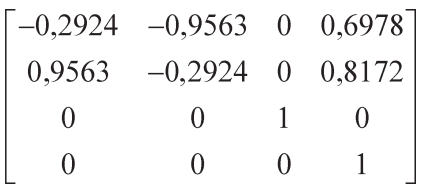

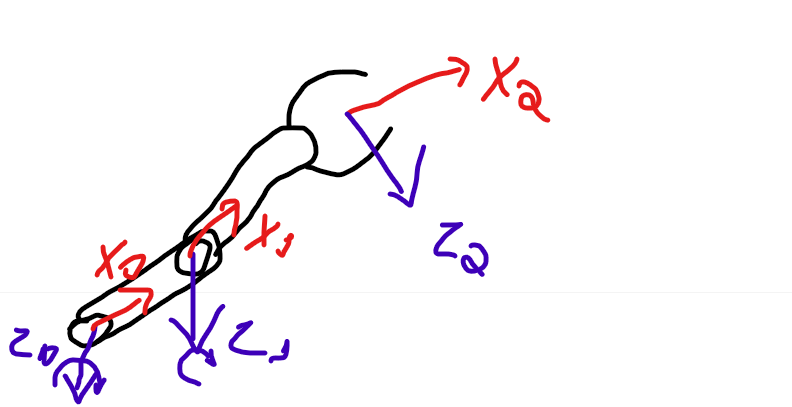

|  link  |   a   |  alpha |    d    |   theta   |

| 0 - 1 |   1   |      0    |    0    |  theta1* |  R

| 1 - 2 |   1   |      0    |    0    |  theta2* |  R

syms theta1 theta2;
DH = [1 0 0 theta1;
      1 0 0 theta2];
H02 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$H02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & \cos\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \sin\left(\theta_{1}\right)+\sigma_{3}+\sigma_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

simplify(H02)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & \cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

theta1_plus_theta2 = atan2d(0.9563,-0.2924)

theta1_plus_theta2 = 107.0016

ct1 = 0.6978 - cosd(theta1_plus_theta2);
st1 = 0.8172 - sind(theta1_plus_theta2);
theta1 = atan2d(st1,ct1)

theta1 = -7.9962

theta2 = theta1_plus_theta2 - theta1

theta2 = 114.9978

DH = [1 0 0 theta1;
      1 0 0 theta2];
H02 = MatProgDenavit(DH)

A01 = 
    0.9903    0.1391         0    0.9903
   -0.1391    0.9903         0   -0.1391
         0         0    1.0000         0
         0         0         0    1.0000

A12 = 
   -0.4226   -0.9063         0   -0.4226
    0.9063   -0.4226         0    0.9063
         0         0    1.0000         0
         0         0         0    1.0000



H02 =    -0.2924   -0.9563         0    0.6979
    0.9563   -0.2924         0    0.8172
         0         0    1.0000         0
         0         0         0    1.0000


### ABB IRB 140

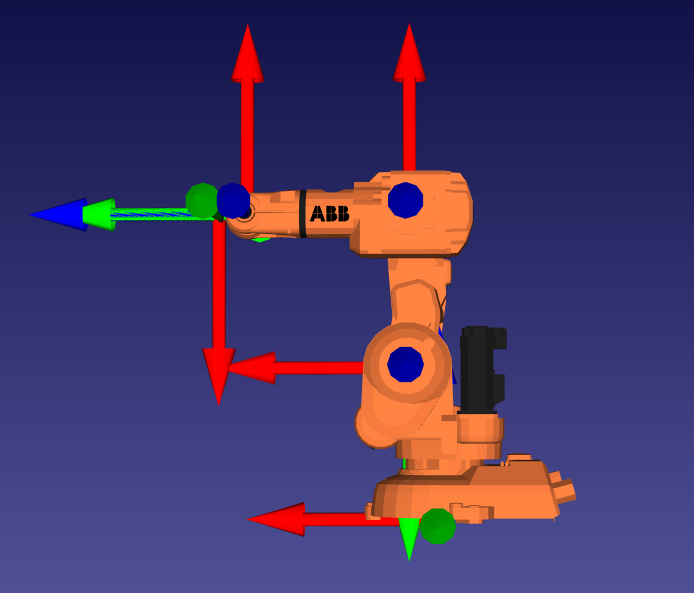

|  link  |   a   | alpha |    d    |        theta        |

| 0 - 1 |  a1  |   -90   |   d1   |        theta1*    |  R

| 1 - 2 |  a2  |     0    |    0    |   theta2* - 90  |  R

| 2 - 3 |   0   |   -90   |    0    |       theta3*     |  P

| 3 - 4 |   0   |  +90   |   d4   |       theta4*     |  R }

| 4 - 5 |   0   |   -90   |    0    |       theta5*     |  R }  Punho esférico

| 5 - 6 |   0   |     0    |   d6   | theta6*  +180 |  R }

theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;
theta6 = 0;

a1 = 70;
a2 = 360;
d1 = 352;
d4 = 380;
d6 = 65;

DH = [a1 -90 d1 theta1;
      a2 0 0 (theta2 - 90);
      0 -90 0 theta3;
      0 +90 d4 theta4;
      0 -90 0 theta5;
      0 0 d6 (theta6 + 180)];

[H06, Alc] = MatProgDenavit(DH)

A01 = 
     1     0     0    70
     0     0     1     0
     0    -1     0   352
     0     0     0     1

A12 = 
     0     1     0     0
    -1     0     0  -360
     0     0     1     0
     0     0     0     1

A23 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A34 = 
     1     0     0     0
     0     0    -1     0
     0     1     0   380
     0     0     0     1

A45 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A56 = 
    -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



H06 =      0     0     1   515
     0     1     0     0
    -1     0     0   712
     0     0     0     1


Alc = 1×6 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


d6 = 65;
d06 = H06(1:3, 4);
R06 = H06(1:3,1:3);
pc = PC(d06,d6,R06)

pc =    450
     0
   712


H03 = Alc{1}*Alc{2}*Alc{3}

H03 =      0     0     1    70
     0    -1     0     0
     1     0     0   712
     0     0     0     1


H36 = H03^-1 * H06

H36 =     -1     0     0     0
     0    -1     0     0
     0     0     1   445
     0     0     0     1


H36 = Alc{4}*Alc{5}*Alc{6}

H36 =     -1     0     0     0
     0    -1     0     0
     0     0     1   445
     0     0     0     1


angsEuler(H36);

theta = 0.000000 | phi + psi = 180.000000


angsRAG(H36);

ThetaN = 0.000000 | ThetaO = -0.000000 | ThetaA = 180.000000


confusao()

phi = thetaA
theta = thetaO
psi = thetaN
